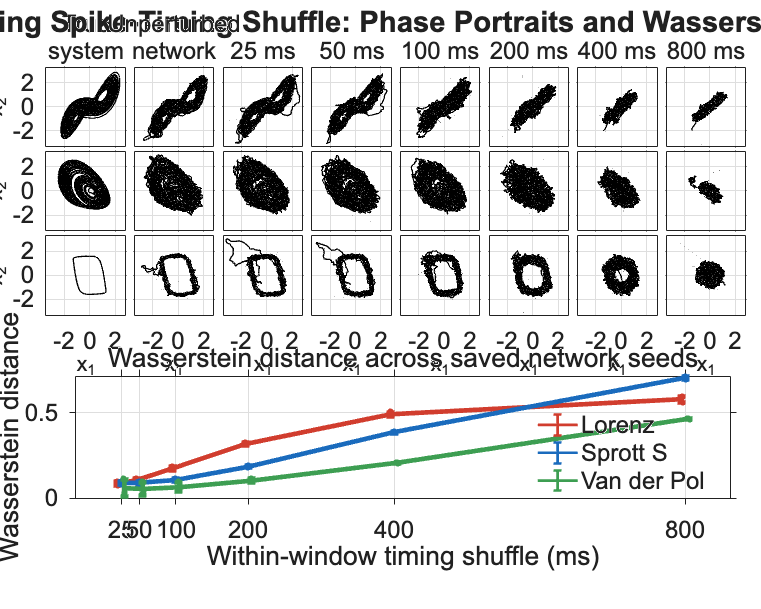

%% Plot Rate-Preserving Spike-Timing Shuffle Analysis
% Loads the newest saved timing-shuffle analysis and renders one editable
% publication figure. It does not rerun a model, shuffle events, or export
% files; use analyse_jitter.mlx to regenerate the saved analysis if needed.

clear; clc; close all;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% Saved Analysis Selection
analysis_dir = fullfile(repo_root, 'outputs', 'publication_analysis', 'jitter_analysis');
files = dir(fullfile(analysis_dir, 'rate_preserving_jitter_analysis_*.mat'));
if isempty(files)
    error('plot_jitter:missingAnalysis', ...
        'No saved jitter analysis was found. Run analyse_jitter.mlx first.');
end
[~, newest_index] = max([files.datenum]);
analysis_file = fullfile(files(newest_index).folder, files(newest_index).name);
S = load(analysis_file, 'saved_jitter_analysis');
if ~isfield(S, 'saved_jitter_analysis') || ~isfield(S.saved_jitter_analysis, 'result') || ...
        ~isfield(S.saved_jitter_analysis, 'schema_version') || ...
        double(S.saved_jitter_analysis.schema_version) < 2
    error('plot_jitter:invalidAnalysis', ...
        ['The selected jitter analysis predates the single-backend baseline fix. ', ...
         'Rerun analyse_jitter.mlx.']);
end
result = S.saved_jitter_analysis.result;

%% Figure Controls
% Phase portraits use the first saved network seed for each system and a
% single neutral trajectory colour. The WD row shows every saved seed, with
% colours reserved exclusively for the three dynamical systems.
cfg = struct();
cfg.font_name = 'Arial';
cfg.figure_width_in = 16;
cfg.figure_height_in = 12.8;
cfg.tick_font_size = 18;
cfg.axis_label_font_size = 16;
cfg.panel_title_font_size = 18;
cfg.figure_title_font_size = 22;
% Use Inf to label every saved shuffle-window condition on the WD axis.
cfg.wd_tick_count = Inf;
% Normalized figure-space controls for the publication layout.
cfg.title_height = .035;
cfg.figure_top_margin = .02;
cfg.title_to_phase_gap = .055;
cfg.phase_to_wd_gap = .1;
cfg.wd_panel_height = .20;
cfg.figure_bottom_margin = .055;
cfg.phase_left_margin = .060;
cfg.phase_right_margin = .020;
cfg.phase_column_gap = .012;
cfg.phase_row_gap = .008;
cfg.phase_line_width = 1.0;
cfg.wd_line_width = 3.5;
cfg.phase_color = [0 0 0];
cfg.system_colors = [0.82 0.24 0.18; 0.10 0.42 0.74; 0.24 0.62 0.32];
cfg.system_ids = {'dynamical_systems_lorenz', 'dynamical_systems_sprotts', 'dynamical_systems_vanderpol'};
cfg.system_labels = {'Lorenz', 'Sprott S', 'Van der Pol'};

systems = select_systems(result.systems, cfg.system_ids);
condition_count = numel(systems(1).seed_results(1).conditions);
assert_matching_conditions(systems, condition_count);
shared_phase_limits = global_phase_limits(systems);

%% Single Combined Figure
% Rows 1-3 compare truth, unperturbed network output, and each timing-shuffle
% condition in phase space. Row 4 compares phase-portrait WD across systems.
n_columns = condition_count + 2;
fig = figure('Color', 'w', 'Units', 'inches', ...
    'Position', [1 1 cfg.figure_width_in cfg.figure_height_in]);
title_bottom = 1 - cfg.figure_top_margin - cfg.title_height;
phase_top = title_bottom - cfg.title_to_phase_gap;
phase_width = 1 - cfg.phase_left_margin - cfg.phase_right_margin;
phase_axis_width = (phase_width - (n_columns-1)*cfg.phase_column_gap) / n_columns;
% A normalized square has a height scaled by the figure's physical aspect
% ratio. This prevents axis square from adding hidden vertical whitespace.
phase_axis_height = phase_axis_width * cfg.figure_width_in / cfg.figure_height_in;
phase_group_height = 3*phase_axis_height + 2*cfg.phase_row_gap;
phase_bottom = phase_top - phase_group_height;
wd_top = phase_bottom - cfg.phase_to_wd_gap;
wd_bottom = wd_top - cfg.wd_panel_height;
if phase_axis_width <= 0 || phase_axis_height <= 0 || wd_bottom < cfg.figure_bottom_margin
    error('plot_jitter:invalidLayout', 'The phase-portrait spacing controls leave no room for axes.');
end
phase_axes = gobjects(numel(systems), n_columns);
for system_index = 1:numel(systems)
    seed_result = systems(system_index).seed_results(1);
    example = seed_result.example;
    trajectories = [{example.truth}, {example.baseline}, example.shuffled];
    labels = cell(1,n_columns);
    labels{1} = {'True', 'system'};
    labels{2} = {'Unperturbed', 'network'};
    labels(3:end) = arrayfun(@shuffle_label, seed_result.conditions, 'UniformOutput', false);
    for column_index = 1:n_columns
        left = cfg.phase_left_margin + (column_index-1) * (phase_axis_width + cfg.phase_column_gap);
        bottom = phase_bottom + (3-system_index) * (phase_axis_height + cfg.phase_row_gap);
        ax = axes(fig, 'Units', 'normalized', 'Position', [left bottom phase_axis_width phase_axis_height]);
        phase_axes(system_index,column_index) = ax;
        plot_phase_portrait(ax, trajectories{column_index}, shared_phase_limits, cfg);
        if system_index == 1
            title(ax, labels{column_index}, 'FontWeight', 'normal', 'FontSize', cfg.panel_title_font_size);
        end
        if column_index == 1
            ylabel(ax, sprintf('%s\nx_2', cfg.system_labels{system_index}), 'FontSize', cfg.axis_label_font_size);
        else
            ylabel(ax, '');
            set(ax, 'YTickLabel', []);
        end
        if system_index == numel(systems)
            xlabel(ax, 'x_1', 'FontSize', cfg.axis_label_font_size);
        else
            xlabel(ax, '');
            set(ax, 'XTickLabel', []);
        end
    end
end

ax_wd = axes(fig, 'Units', 'normalized', 'Position', [.10 wd_bottom .86 cfg.wd_panel_height]);
plot_wasserstein_row(ax_wd, systems, cfg);
title_x = (.5 - cfg.phase_left_margin) / phase_axis_width;
title_y = 1 + (title_bottom + cfg.title_height/2 - phase_top) / phase_axis_height;

text(phase_axes(1,1), title_x, title_y, ...
    'Rate-Preserving Spike-Timing Shuffle: Phase Portraits and Wasserstein Distance', ...

Plotted one combined jitter figure from rate_preserving_jitter_analysis_20260722_171727.mat.


    'Units', 'normalized', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Clipping', 'off', ...
    'FontName', cfg.font_name, 'FontSize', cfg.figure_title_font_size, 'FontWeight', 'bold');

fprintf('Plotted one combined jitter figure from %s.\n', files(newest_index).name);

function systems = select_systems(all_systems, required_ids)
systems = repmat(all_systems(1), 1, numel(required_ids));
for ii = 1:numel(required_ids)
    index = find(strcmp({all_systems.task_id}, required_ids{ii}), 1);
    if isempty(index)
        error('plot_jitter:missingSystem', 'Saved jitter analysis does not contain %s.', required_ids{ii});
    end
    systems(ii) = all_systems(index);
end
end

function assert_matching_conditions(systems, condition_count)
reference = double([systems(1).seed_results(1).conditions.window_s]);
for ii = 1:numel(systems)
    if isempty(systems(ii).seed_results) || numel(systems(ii).seed_results(1).conditions) ~= condition_count
        error('plot_jitter:conditionMismatch', 'The saved systems do not have matching shuffle conditions.');
    end
    current = double([systems(ii).seed_results(1).conditions.window_s]);
    if ~isequal(reference, current)
        error('plot_jitter:conditionMismatch', 'The saved systems use different shuffle-window values.');
    end
end
end

function plot_phase_portrait(ax, trajectory, limits, cfg)
trajectory = double(trajectory);
if size(trajectory, 2) < 2
    error('plot_jitter:badTrajectory', 'Phase portraits require at least two state dimensions.');
end
plot(ax, trajectory(:,1), trajectory(:,2), '-', 'Color', cfg.phase_color, 'LineWidth', cfg.phase_line_width);
grid(ax, 'on'); box(ax, 'on'); axis(ax, 'square'); xlim(ax, limits(1:2)); ylim(ax, limits(3:4));
set(ax, 'FontName', cfg.font_name, 'FontSize', cfg.tick_font_size, 'LineWidth', .7, 'TickDir', 'out');
end

function limits = global_phase_limits(systems)
values = zeros(0,2);
for system_index = 1:numel(systems)
    values = [values; example_phase_values(systems(system_index).seed_results(1).example)]; %#ok<AGROW>
end
if isempty(values)
    error('plot_jitter:noFiniteTrajectory', 'The saved examples contain no finite phase-portrait samples.');
end
x = values(:,1); y = values(:,2);
dx = max(max(x)-min(x), eps); dy = max(max(y)-min(y), eps);
limits = [min(x)-.04*dx, max(x)+.04*dx, min(y)-.04*dy, max(y)+.04*dy];
end

function values = example_phase_values(example)
values = [double(example.truth(:,1:2)); double(example.baseline(:,1:2))];
for ii = 1:numel(example.shuffled)
    values = [values; double(example.shuffled{ii}(:,1:2))]; %#ok<AGROW>
end
values = values(all(isfinite(values),2),:);
if isempty(values)
    error('plot_jitter:noFiniteTrajectory', 'An example phase portrait contains no finite samples.');
end
end

function plot_wasserstein_row(ax, systems, cfg)
condition_count = numel(systems(1).seed_results(1).conditions);
window_ms = 1e3 .* double([systems(1).seed_results(1).conditions.window_s]);
minimum_spacing = min(diff(window_ms));
if isempty(minimum_spacing) || minimum_spacing <= 0, minimum_spacing = max(window_ms,1); end
offsets = linspace(-.18,.18,numel(systems)) .* minimum_spacing;
legend_handles = gobjects(1,numel(systems));
hold(ax, 'on');
for system_index = 1:numel(systems)
    seed_results = systems(system_index).seed_results;
    means = nan(1, condition_count); deviations = nan(1, condition_count);
    for condition_index = 1:condition_count
        values = arrayfun(@(R) double(R.conditions(condition_index).wd), seed_results);
        values = values(isfinite(values));
        if isempty(values), continue; end
        x = window_ms(condition_index) + offsets(system_index) + deterministic_jitter(numel(values), .035 * minimum_spacing);
        scatter(ax, x, values, 22, 'filled', 'MarkerFaceColor', cfg.system_colors(system_index,:), ...
            'MarkerEdgeColor', 'none');
        means(condition_index) = mean(values);
        deviations(condition_index) = std(values, 0);
    end
    legend_handles(system_index) = errorbar(ax, window_ms+offsets(system_index), means, deviations, '-', ...
        'Color', cfg.system_colors(system_index,:), 'LineWidth', cfg.wd_line_width, 'CapSize', 6, ...
        'DisplayName', cfg.system_labels{system_index});
end
hold(ax, 'off'); grid(ax, 'on'); box(ax, 'on');
tick_indices = unique(round(linspace(1,condition_count,min(cfg.wd_tick_count,condition_count))));
xticks(ax, window_ms(tick_indices)); xticklabels(ax, arrayfun(@(x)sprintf('%.0f',x),window_ms(tick_indices),'UniformOutput',false));
x_pad = .08 * max(window_ms(end)-window_ms(1), minimum_spacing);
xlim(ax, [window_ms(1)-x_pad, window_ms(end)+x_pad]);
xlabel(ax, 'Within-window timing shuffle (ms)', 'FontSize', cfg.axis_label_font_size);
ylabel(ax, {'Phase-portrait', 'Wasserstein distance'}, 'FontSize', cfg.axis_label_font_size);
title(ax, 'Wasserstein distance across saved network seeds', 'FontWeight', 'normal', 'FontSize', cfg.panel_title_font_size);
legend(ax, legend_handles, cfg.system_labels, 'Location', 'best', 'Box', 'off', 'FontSize', cfg.tick_font_size);
set(ax, 'FontName', cfg.font_name, 'FontSize', cfg.tick_font_size, 'LineWidth', .7, 'TickDir', 'out');
end

function label = shuffle_label(condition)
label = sprintf('%.0f ms', 1e3 * double(condition.window_s));
end

function jitter = deterministic_jitter(n, width)
index = (1:n).';
jitter = width .* (2 .* mod(sin(index .* 12.9898) .* 43758.5453, 1) - 1);
end
